Question 1

a) explicit multistep method

b) implicit multistep method

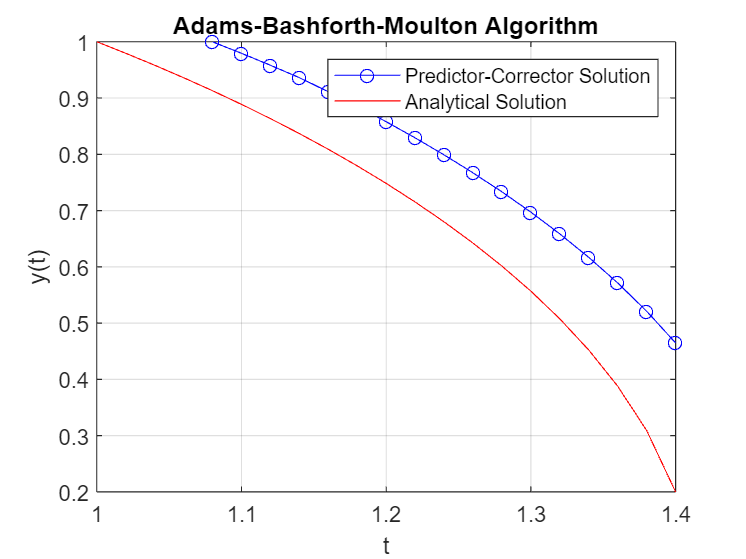

f = @(t, y) -t / y;

t_start = 1.08;
t_end = 1.4;
h = 0.02;
t = t_start:h:t_end;

y0 = [1, 0.9796, 0.9583, 0.9362];

y = zeros(1, length(t));

y(1:length(y0)) = y0;

for k = 4:length(t)-1
    fk_minus_3 = f(t(k-3), y(k-3));
    fk_minus_2 = f(t(k-2), y(k-2));
    fk_minus_1 = f(t(k-1), y(k-1));
    fk = f(t(k), y(k));
    
    p_k_plus_1 = y(k) + (h/24)*(-9*fk_minus_3 + 37*fk_minus_2 - 59*fk_minus_1 + 55*fk);

    f_k_plus_1 = -t(k+1) / p_k_plus_1;
    y(k+1) = y(k) + (h/24)*(fk_minus_2 - 5*fk_minus_1 + 19*fk + 9*f_k_plus_1);
end

t_analytical = 1:h:1.4;
y_analytical = sqrt(2 - t_analytical.^2);

plot(t, y, 'b-o', t_analytical, y_analytical, 'r-');
xlabel('t');
ylabel('y(t)');
title('Adams-Bashforth-Moulton Algorithm');
legend('Predictor-Corrector Solution', 'Analytical Solution');
grid on;

Question 2

P0 = [1, 1, 1];
grad_f = @(x, y, z) [4*x - 2*y, 2*y - 2*x + z - 7, 3*z^2 + y - 4];
f = @(x, y, z) 2*x^2 + y^2 + z^3 - 2*x*y + y*z - 7*y - 4*z;

grad = grad_f(P0(1), P0(2), P0(3));
d = -grad;

alpha = 0.1;
max_iter = 100;
%a,b
[a, b] = bracket_minimum(P0, d, f, alpha, max_iter);
disp(['Bracketed interval: a = ', num2str(a), ', b = ', num2str(b)]);

Bracketed interval: a = 0.2, b = 0.3


%c
[x_min, f_min] = golden_ratio_search(P0, d, f, a, b, max_iter);

disp(['Minimum point found at: ', mat2str(x_min)]); % minimum bracketed

Minimum point found at: [0.411766742003197 2.76469977399041 1]


disp(['Minimum value of the function: ', num2str(f_min)]); % golden ratio

Minimum value of the function: -13.8824


Question 3

A = [-2 -4 2;
     -2 1 2;
     4 2 5];

[V, D] = eig(A);

disp('Eigenvalues:');

Eigenvalues:


disp(diag(D));

   -5.0000
    3.0000
    6.0000



disp('Eigenvectors:');

Eigenvectors:


disp(V);

    0.8165    0.5345    0.0584
    0.4082   -0.8018    0.3505
   -0.4082   -0.2673    0.9347




% Verification
for k = 1:size(V, 2)
    lambda = D(k, k);
    v = V(:, k);
    result = A * v;
    expected = lambda * v;
    fprintf('Testing eigenvector %d:\n', k);
    fprintf('A * v:\n');
    disp(result);
    fprintf('lambda * v:\n');
    disp(expected);
    fprintf('Error:\n');
    disp(norm(result - expected));
end

Testing eigenvector 1:


A * v:


   -4.0825
   -2.0412
    2.0412



lambda * v:


   -4.0825
   -2.0412
    2.0412



Error:


   5.7044e-15



Testing eigenvector 2:


A * v:


    1.6036
   -2.4054
   -0.8018



lambda * v:


    1.6036
   -2.4054
   -0.8018



Error:


   2.9873e-15



Testing eigenvector 3:


A * v:


    0.3505
    2.1031
    5.6084



lambda * v:


    0.3505
    2.1031
    5.6084



Error:


   1.2671e-15



BONUS 1

load("C:\Users\adi03\Downloads\A.mat");

b = ones(size(A,1), 1);

[x,flag,relres,iter,resvec] = pcg(A, b, 1e-6, 1000);

fprintf('Number of iterations without preconditioner: %d\n', iter);

Number of iterations without preconditioner: 156


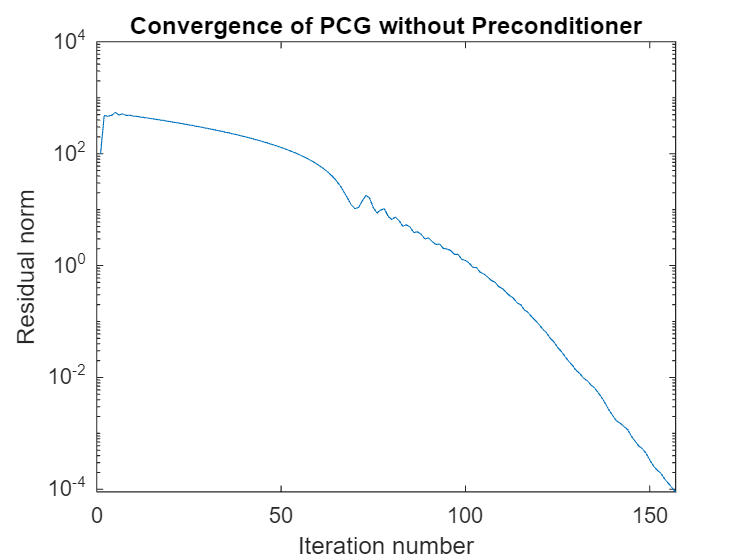


figure;
semilogy(resvec);
title('Convergence of PCG without Preconditioner');
xlabel('Iteration number');
ylabel('Residual norm');


fprintf('Norm of residual without preconditioner: %.4e\n', norm(A*x - b));

Norm of residual without preconditioner: 8.9952e-05


BONUS 2

load("C:\Users\adi03\Downloads\M.mat"); 
[x_precond,flag_precond,relres_precond,iter_precond,resvec_precond] = pcg(A, b, 1e-6, 1000, M);

fprintf('Number of iterations with preconditioner: %d\n', iter_precond);

Number of iterations with preconditioner: 59


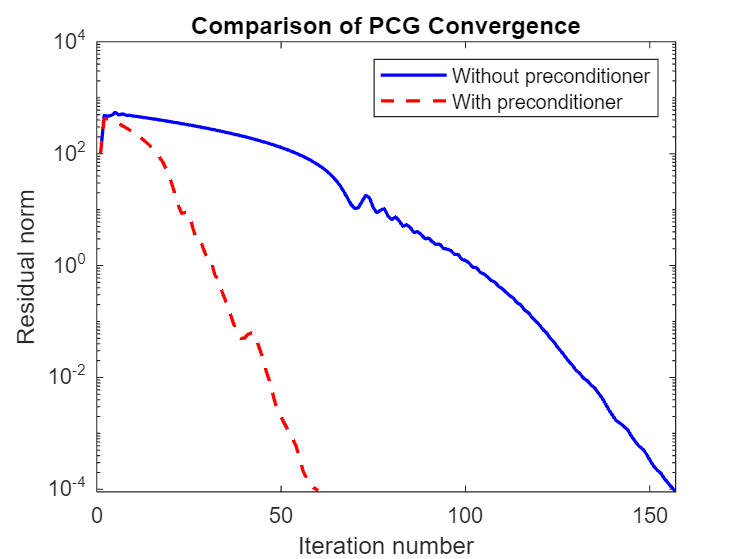


figure;
semilogy(resvec, 'b-', 'LineWidth', 1.5); hold on;
semilogy(resvec_precond, 'r--', 'LineWidth', 1.5);
legend('Without preconditioner', 'With preconditioner');
title('Comparison of PCG Convergence');
xlabel('Iteration number');
ylabel('Residual norm');
hold off;

function [a, b] = bracket_minimum(P0, d, f, alpha, max_iter)
    a = 0;
    b = alpha;
    fa = f_value(P0, d, f, a);
    fb = f_value(P0, d, f, b);

    if fb > fa
        d = -d;
        temp = a;
        a = b;
        b = temp;
        temp = fa;
        fa = fb;
        fb = temp;
    end

    for i = 1:max_iter
        c = b + alpha;
        fc = f_value(P0, d, f, c);
        if fc > fb
            return;
        end
        a = b;
        b = c;
        fa = fb;
        fb = fc;
    end
end

function val = f_value(P, d, f, t)
    x = P(1) + t * d(1);
    y = P(2) + t * d(2);
    z = P(3) + t * d(3);
    val = f(x, y, z);
end

function [x_min, f_min] = golden_ratio_search(P0, d, f, a, b, max_iter)
    phi = (1 + sqrt(5)) / 2;
    resphi = 2 - phi;
    
    x1 = a + resphi * (b - a);
    x2 = b - resphi * (b - a);
    f1 = f_value(P0, d, f, x1);
    f2 = f_value(P0, d, f, x2);
    
    for i = 1:max_iter
        if f1 < f2
            b = x2;
            x2 = x1;
            f2 = f1;
            x1 = a + resphi * (b - a);
            f1 = f_value(P0, d, f, x1);
        else
            a = x1;
            x1 = x2;
            f1 = f2;
            x2 = b - resphi * (b - a);
            f2 = f_value(P0, d, f, x2);
        end
        if abs(b - a) < 1e-5
            break;
        end
    end
    
    if f1 < f2
        x_min = P0 + x1 * d;
        f_min = f1;
    else
        x_min = P0 + x2 * d;
        f_min = f2;
    end
end